## Problem 9a

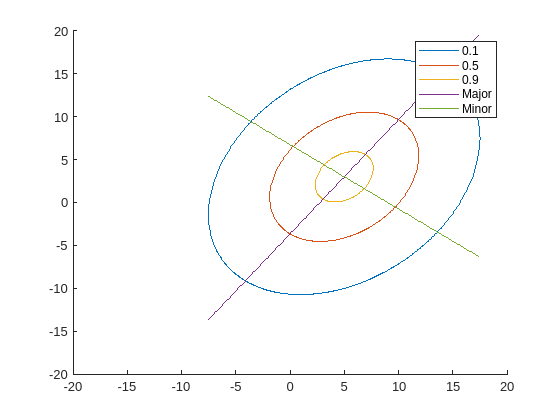

clear;
%specify mu and sigma
mu = [5,3]; 
sigma = [34, 12; 12 41]; 

figure;
hold on;

[Z1,T_w1] = plot_contour(mu,sigma,0.1);
[Z2,T_w2] = plot_contour(mu,sigma,0.5);
[Z3,T_w3] = plot_contour(mu,sigma,0.9);


plot_maj_and_minor(Z1,T_w1,mu);
legend;
xlim([-20,20])
ylim([-20,20])


hold off;

### Problem 9b

p_x_y = sigma(1,2) / (sqrt(sigma(1,1))*sqrt(sigma(2,2)))

p_x_y = 0.3214

## Problem 9c

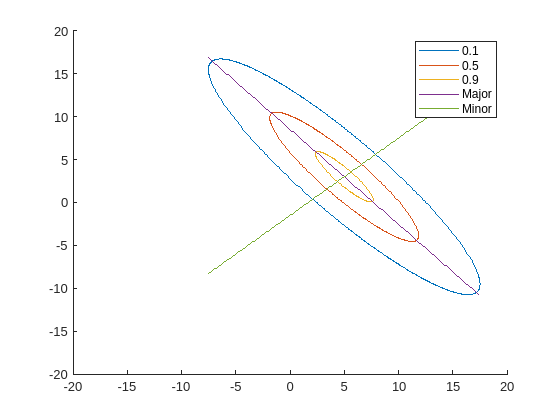

clear;
%specify mu and sigma
mu = [5,3]; 
sigma = [34, -34; -34 41]; 

figure;
hold on;

[Z1,T_w1] = plot_contour(mu,sigma,0.1);
[Z2,T_w2] = plot_contour(mu,sigma,0.5);
[Z3,T_w3] = plot_contour(mu,sigma,0.9);


plot_maj_and_minor(Z1,T_w1,mu);

legend;
xlim([-20,20])
ylim([-20,20])

hold off;

p_x_y = sigma(1,2) / (sqrt(sigma(1,1))*sqrt(sigma(2,2)))

p_x_y = -0.9106

function [Z,T_w] = plot_contour(mu,sigma,k)
    x_1_max = sqrt(-2 * log(k));
    x = -1 * x_1_max : 0.01: x_1_max;
    y = sqrt(-2 * log(k) - x.^(2));
    
    %get the negative x_2 terms
    x = [x,flip(x)];
    y = [y,flip(-1 * y)];
    
    %combine the data into a single variable
    W = [x;y];
    %compute the eigen value decomposition
    [V,D] = eig(sigma);
    T_w = V * D^(1/2) * transpose(V);
    Z = (T_w * W) + transpose(mu); 
    
    
    %plot the scaled and translated values
    plot(Z(1,:),Z(2,:),"DisplayName",num2str(k))
end

function plot_maj_and_minor(Z,T_w,mu)
    %get the eigen vectors for the inverted T_x
    [V,D] = eig(T_w);

    %plot the major axis
    x = min(Z(1,:)) - mu(1): 0.1 : max(Z(1,:)) - mu(1);
    S_maj = V(2,2)/V(1,2);
    y =  S_maj * x;
    plot(x + mu(1),y + mu(2),"DisplayName","Major")

    %plot the minor axis
    x = min(Z(1,:)) - mu(1): 0.1 : max(Z(1,:)) - mu(1);
    S_min = V(2,1)/V(1,1);
    y =  S_min * x;
    plot(x + mu(1),y + mu(2),"DisplayName","Minor")
    
end